# Image Resampling

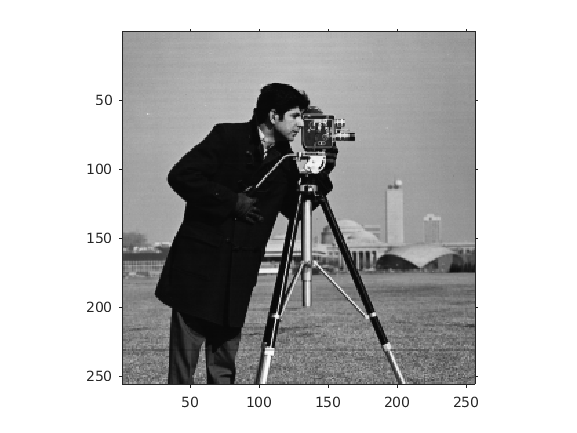

img = imread("cameraman.tif");
figure(1);
imshow(img);
axis on;

## Interpolate pixel at (1,2)

figure(2);

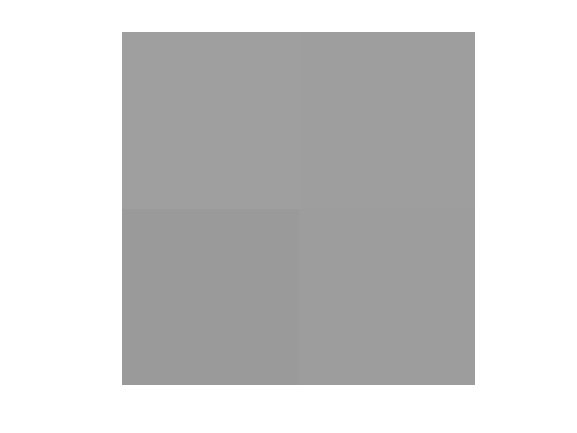

imshow(img(1:2,2:3));

img(1,2)

ans = uint8
159

interp2(double(img),2,1)

ans = 159

## Upsampling using interp2

figure(3)

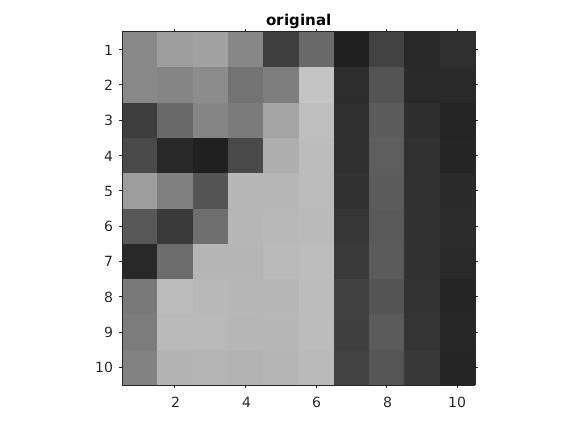

imshow(img(70:79,125:134));
title("original");
axis on;

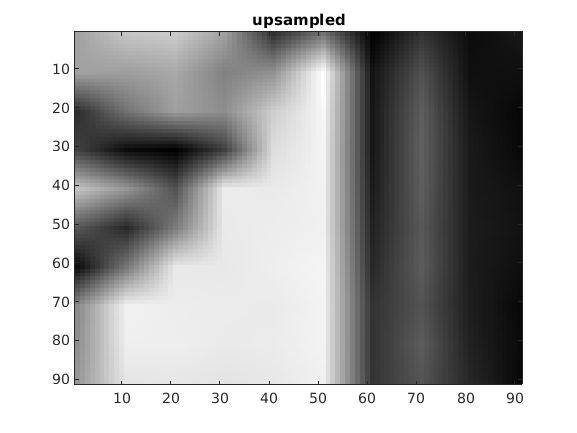

[C,R] = meshgrid(125:0.1:134,70:0.1:79);
img_upsamp = interp2(double(img),C,R,'linear');%default is linear
figure(4);
imagesc(img_upsamp);
colormap('gray');
title("upsampled");
axis on;

## Upscaling the entire image

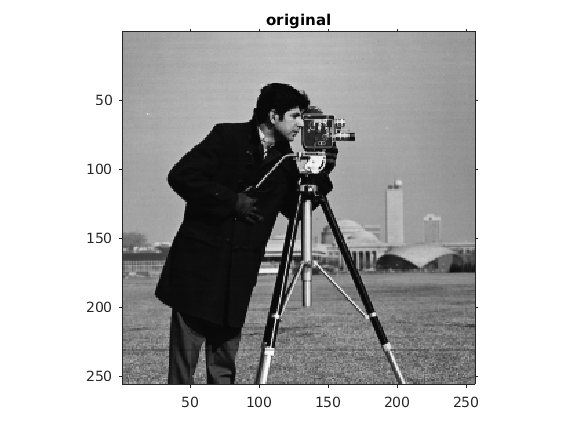

%New image size
nr = 1000;
nc = 1500;
figure(5);
imshow(img);
title("original");
axis on;
[r,c] = size(img);
[C,R] = meshgrid(1:(c-1)/(nc-1):c,1:(r-1)/(nr-1):r);
upsized = interp2(double(img),C,R,'linear');
figure(6);

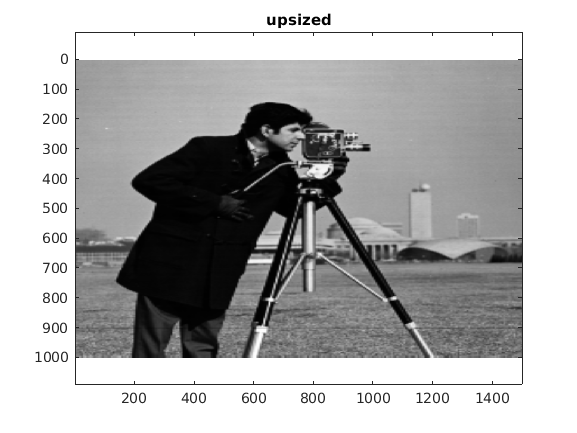

imagesc(upsized);
colormap('gray');
title("upsized");
axis on;
axis equal;

## Pixelate face(downsampling)

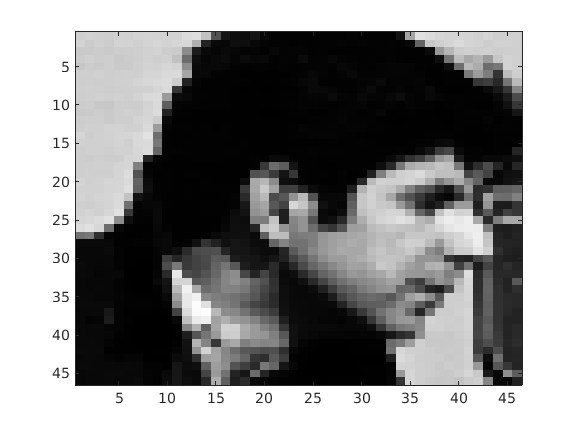

face = img(40:85,90:135);
imagesc(face);

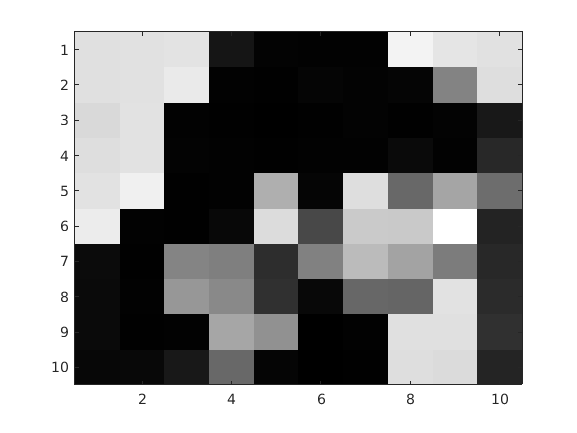

%coarse resolution
nr = 10;
nc = 10;
[r,c] = size(face);
[C,R] = meshgrid(1:(c-1)/(nc-1):c,1:(r-1)/(nr-1):r);
downface = interp2(double(face),C,R,'linear');
imagesc(downface);
colormap('gray');

## Place pixelated face back to original image

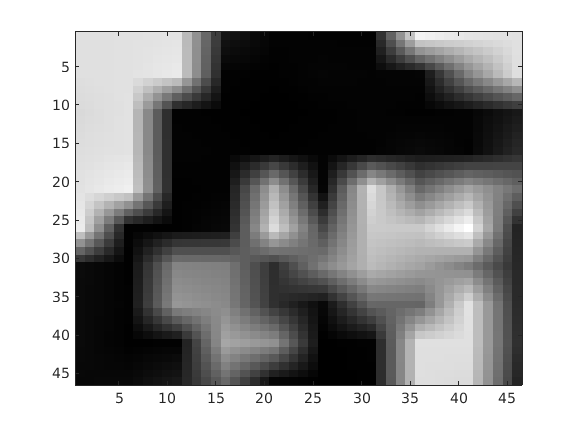

[C,R] = meshgrid(1:(nc-1)/(c-1):nc,1:(nr-1)/(r-1):nr);
anonface = interp2(downface,C,R,'linear');
imagesc(anonface);%image appears smooth because linear interpolation was used

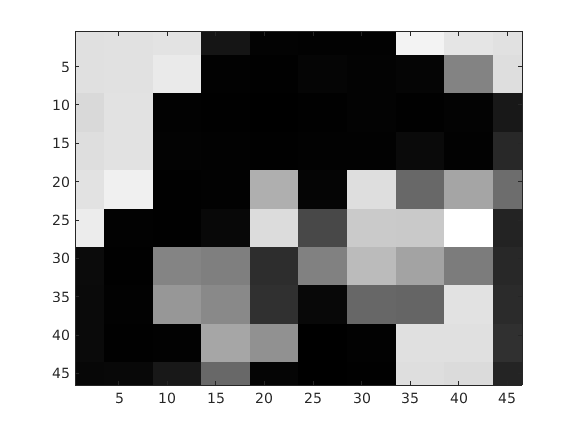

anonface = interp2(downface,C,R,'nearest');
imagesc(anonface);

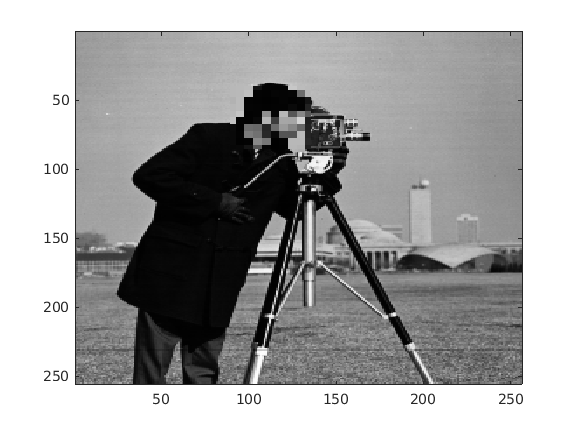

img(40:85,90:135) = anonface;
imagesc(img);